## Parameter Pre-Setting

clear 
clc

V0 = 0.895;                     % input swing
C1 = 38.72E-12;                 % load cap
Fs = 100E6;                     % sample rate
wt = [101, 249, 499] / 1024;     
Fin = wt .* Fs;                 % input frequency (Hz)
Ron0 = 6.5;                     % On-Resistance (ohm)
L = [0.2, 0.4, 0.6,0.8, 1, 2, 3];
alpha = [-0.1, 0.8, 1.11, 1.26, 1.36, 1.55, 1.61];


## Calculation Compresion

for i = 1:length(alpha)
    temp = getHD_new(Ron0, V0, C1, Fin, alpha(i));      % for all length
    TXT = ['L = ', num2str(L(i)), 'um, alpha = ', ...
        num2str(alpha(i)), ';'];
    disp(TXT)
    HD3 = reshape(temp(1,2,:),1,3)
    HD3S = getHD3_Simplified(Ron0, V0, C1, Fin, alpha(i))

end

L = 0.2um, alpha = -0.1;


HD3 =   -88.9407  -73.4062  -61.5655


HD3S =   -94.4606  -78.7855  -66.7095


L = 0.4um, alpha = 0.8;


HD3 =   -93.7883  -78.2353  -66.3648


HD3S =  -109.2679  -93.5928  -81.5167


L = 0.6um, alpha = 1.11;


HD3 =   -96.4154  -80.9092  -69.1204


HD3S =  -114.4606  -98.7855  -86.7095


L = 0.8um, alpha = 1.26;


HD3 =   -98.0526  -82.5978  -70.9005


HD3S =  -106.9890  -91.3139  -79.2378


L = 1um, alpha = 1.36;


HD3 =   -99.3492  -83.9489  -72.3503


HD3S =  -104.1624  -88.4873  -76.4113


L = 2um, alpha = 1.55;


HD3 =  -102.5334  -87.3289  -76.1009


HD3S =  -100.4812  -84.8061  -72.7301


L = 3um, alpha = 1.61;


HD3 =  -103.8458  -88.7535  -77.7494


HD3S =   -99.5819  -83.9068  -71.8307


## Fin vs. HD3

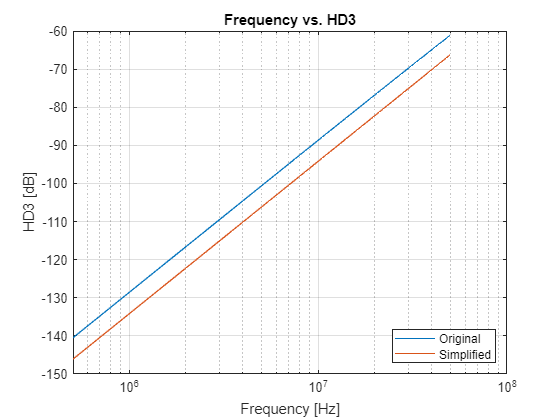

fin = linspace(0,0.5,100) * Fs;
% for Ron = 6.5 hms, L = 200n;
temp = getHD_new(Ron0, V0, C1, fin, alpha(1));
HD3_fin = reshape(temp(1,2,:), 1, length(fin));
HD3S_fin = getHD3_Simplified(Ron0, V0, C1, fin, alpha(1));

figure
semilogx(fin, [HD3_fin; HD3S_fin]);
box on;
grid on;
xlabel("Frequency [Hz]");
ylabel("HD3 [dB]");
legend(["Original", "Simplified"], 'Location','southeast')
title("Frequency vs. HD3")

## Ron vs. HD3

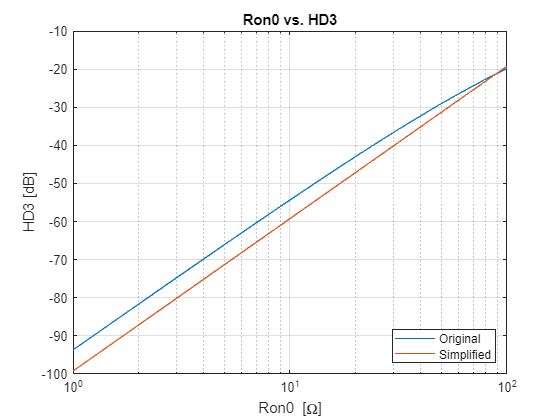

ron = linspace(1,100);
FIN = Fin(3);       
% for Fin = 499/1024 Fs, L = 200n;
temp = getHD_new(ron, V0, C1, FIN, alpha(1));
HD3_ron = reshape(temp(:,2), 1, length(ron));
HD3S_ron = getHD3_Simplified(ron, V0, C1, FIN, alpha(1));

figure
semilogx(ron, [HD3_ron; HD3S_ron]);
box on;
grid on;
xlabel("Ron0 [\Omega]");
ylabel("HD3 [dB]");
legend(["Original", "Simplified"], 'Location','southeast')
title("Ron0 vs. HD3")

## CL vs. HD3

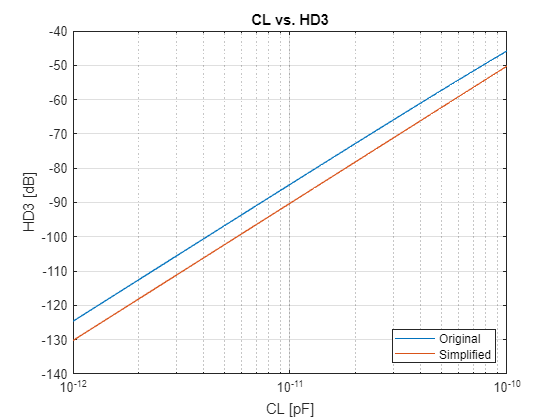

cl = linspace(1,100).*1E-12;
FIN = Fin(3);           
% for Fin = 499/1024 Fs, L = 200n;
HD3_cl = zeros(1,length(cl));
for i = 1:length(cl)
    temp = getHD_new(Ron0, V0, cl(i), FIN, alpha(1));
    HD3_cl(i) = temp(2);
end

HD3S_cl = getHD3_Simplified(Ron0, V0, cl, FIN, alpha(1));

figure
semilogx(cl, [HD3_cl; HD3S_cl]);
box on;
grid on;
xlabel("CL [pF]");
ylabel("HD3 [dB]");
legend(["Original", "Simplified"], 'Location','southeast')
title("CL vs. HD3")

## V0 vs. HD3

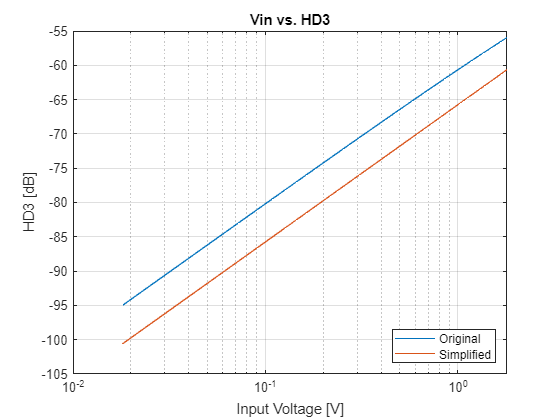

v0 = linspace(0,1.8);
FIN = Fin(3);
% for Ron = 6.5Ohm, CL = 38.72pF, Fin = 499/1024 * Fs;
HD3_v0 = zeros(1,length(v0));
HD3S_v0 = zeros(1,length(v0));

for i = 1:length(v0)
    temp = getHD_new(Ron0, v0(i), C1, FIN, alpha(1));
    HD3_v0(i) = temp(2);
    HD3S_v0(i) = getHD3_Simplified(Ron0, v0(i), C1, FIN, alpha(1));
end

figure
semilogx(v0, [HD3_v0; HD3S_v0]);
box on;
grid on;
xlabel("Input Voltage [V]");
ylabel("HD3 [dB]");
legend(["Original", "Simplified"], 'Location','southeast')
title("Vin vs. HD3")

## Conclusion

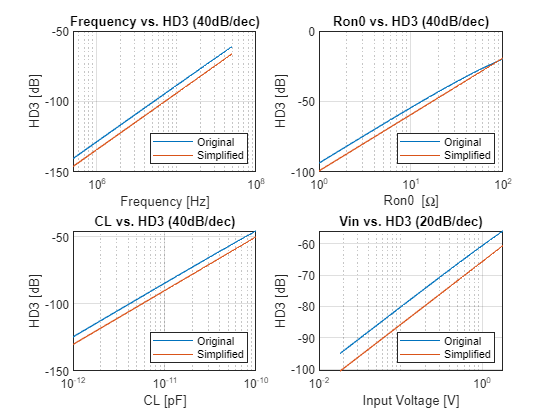

figure
subplot(2,2,1)
semilogx(fin, [HD3_fin; HD3S_fin]);
box on;
grid on;
xlabel("Frequency [Hz]");
ylabel("HD3 [dB]");
legend(["Original", "Simplified"], 'Location','southeast')
title("Frequency vs. HD3 (40dB/dec)")

subplot(2,2,2)
semilogx(ron, [HD3_ron; HD3S_ron]);
box on;
grid on;
xlabel("Ron0 [\Omega]");
ylabel("HD3 [dB]");
legend(["Original", "Simplified"], 'Location','southeast')
title("Ron0 vs. HD3 (40dB/dec)")

subplot(2,2,3)
semilogx(cl, [HD3_cl; HD3S_cl]);
box on;
grid on;
xlabel("CL [pF]");
ylabel("HD3 [dB]");
legend(["Original", "Simplified"], 'Location','southeast')
title("CL vs. HD3 (40dB/dec)")

subplot(2,2,4)
semilogx(v0, [HD3_v0; HD3S_v0]);
box on;
grid on;
xlabel("Input Voltage [V]");
ylabel("HD3 [dB]");
legend(["Original", "Simplified"], 'Location','southeast')
title("Vin vs. HD3 (20dB/dec)")